## Main Model Script 

For each dataset (with $X$ being the spike count over $n$ cue windows and $Y$ being the label), we run the following model

- Logistic Regression

- Decision Tree (with AdaBoost)

- Gaussian Discriminant Analysis (GDA)

- Support Vector Machine (SVM)

- Neural Network 

- PCA (unsupervised learning, just to see what happens) 

## Load Data

directories = {'2023_09_12', '2023_09_14', '2023_09_15'};
% length of coritcal good is different for each date
% adjust X, y accordingly
%cd("Data/sch13/"+directories{1})
cd("Data/sch13/"+directories{2})
%cd("Data/sch13/"+directories{3})
load("data_main.mat")
X = data_main(:, 1:61); % Predictors 1:96 for 09_12, 1:61 for 09_14, 1:86 for 09_15
y = data_main(:, 62);   % Response 97 for 09_12, 62 for 09_14, 97 for 09_15
X = removeLowSumColumns(X); % Remove the neurons that didn't fire significantly
% throughout trial period (reduce variance) 
rng(0) % For reproducibility

Given limited data ($n=100$), we will be running a 10-fold cross validation for most of the models. 

## Logistic Regression

% Setting up 10-fold cross-validation
c = cvpartition(y, 'KFold', 10);

% Initialize vectors to store results
accuracy = zeros(c.NumTestSets, 1);
precision = zeros(c.NumTestSets, 1);
recall = zeros(c.NumTestSets, 1);
f1Scores = zeros(c.NumTestSets, 1);

% Perform logistic regression for each fold
for i = 1:c.NumTestSets
    % Training data for this fold
    trainX = X(training(c, i), :);
    trainY = y(training(c, i));

    % Test data for this fold
    testX = X(test(c, i), :);
    testY = y(test(c, i));

    % Fit logistic regression model
    model = fitglm(trainX, trainY, 'Distribution', 'binomial');

    % Predict on test data
    predictions = predict(model, testX) > 0.5; % Using 0.5 as threshold

    % Calculate accuracy
    accuracy(i) = mean(predictions == testY);

    % Calculate precision, recall, and F1 score
    TP = sum((predictions == 1) & (testY == 1));
    FP = sum((predictions == 1) & (testY == 0));
    FN = sum((predictions == 0) & (testY == 1));

    precision(i) = TP / (TP + FP);
    recall(i) = TP / (TP + FN);
    f1Scores(i) = 2 * (precision(i) * recall(i)) / (precision(i) + recall(i));
end


% Display the average F1 score across all folds
LRmeanF1Score = mean(f1Scores);
% disp(['Mean F1 Score: ', num2str(LRmeanF1Score)]);

% Overall performance
LRmeanAccuracy = mean(accuracy);
% disp(['Logistic Regression Mean Accuracy: ', num2str(LRmeanAccuracy)]);

## Decision Tree with AdaBoost

clear model 
% Create a default decision tree template
t = templateTree('MaxNumSplits', 1); % Use decision stumps

% Train the AdaBoostM1 model with decision trees as weak learners
boostedMdl = fitcensemble(X, y, ...
                          'Method', 'AdaBoostM1', ...
                          'Learners', t, ...
                          'NumLearningCycles', 40, ... % Number of boosting iterations
                          'LearnRate', 0.08, ... % Learning rate
                          'CrossVal', 'on', ... % Turn on cross-validation
                          'KFold', 10); % 10-fold cross-validation

% Evaluate the cross-validated loss
cvLoss = kfoldLoss(boostedMdl);

% Display the loss
%disp(['Decision Tree 10-fold cross-validated loss: ', num2str(cvLoss)]);
% Calculate and display the cross-validated accuracy
predictedLabels = kfoldPredict(boostedMdl);
DecisionTreeaccuracy = sum(predictedLabels == y) / numel(y);
%disp(['Decision Tree 10-fold cross-validated accuracy: ', num2str(DecisionTreeaccuracy)]);

% F1 score
% Initialize vectors to store results for each fold
precision = zeros(boostedMdl.KFold, 1);
recall = zeros(boostedMdl.KFold, 1);
f1Scores = zeros(boostedMdl.KFold, 1);

% Get the predicted labels from k-fold cross-validation
predictedLabels = kfoldPredict(boostedMdl);

% Calculate F1 score for each fold
for i = 1:boostedMdl.KFold
    % Indices for the test set of the i-th fold
    testIdx = test(boostedMdl.Partition, i);

    % True labels and predicted labels for the i-th fold
    trueLabels = y(testIdx);
    foldPredictedLabels = predictedLabels(testIdx);

    % Calculate TP, FP, FN
    TP = sum((foldPredictedLabels == 1) & (trueLabels == 1));
    FP = sum((foldPredictedLabels == 1) & (trueLabels == 0));
    FN = sum((foldPredictedLabels == 0) & (trueLabels == 1));

    % Calculate precision and recall
    precision(i) = TP / (TP + FP);
    recall(i) = TP / (TP + FN);

    % Calculate F1 score
    f1Scores(i) = 2 * (precision(i) * recall(i)) / (precision(i) + recall(i));
end

% Compute the mean F1 score across all folds
DTmeanF1Score = mean(f1Scores);
%disp(['Decision Tree AdaBoost 10-fold cross-validated F1 Score: ', num2str(meanDTF1Score)]);

## Gaussian Discriminant Analysis (GDA)

% Split the data into a training set and a test set
cv = cvpartition(size(X, 1), 'HoldOut', 0.1); %change 
idx = cv.test;
XTrain = X(~idx, :);
YTrain = y(~idx);
XTest = X(idx, :);
YTest = y(idx);

% Fit GDA model
gdaModel = fitcdiscr(XTrain, YTrain, 'DiscrimType', 'linear');

% Predict labels for the test set
YPred = predict(gdaModel, XTest);

% Evaluate the model
GDAaccuracy = sum(YPred == YTest) / numel(YTest);
%disp(['GDA Accuracy: ', num2str(GDAaccuracy)]);
% Calculate TP, FP, FN for the F1 score
TP = sum((YPred == 1) & (YTest == 1));
FP = sum((YPred == 1) & (YTest == 0));
FN = sum((YPred == 0) & (YTest == 1));

% Calculate precision and recall
precision = TP / (TP + FP);
recall = TP / (TP + FN);

% Handle cases where the denominator is zero
if (precision + recall) == 0
    GDAf1Score = 0;
else
    % Calculate F1 score
    GDAf1Score = 2 * (precision * recall) / (precision + recall);
end

% Display F1 score
% disp(['GDA F1 Score: ', num2str(GDAf1Score)]);

## Support Vector Machine (SVM)

% Split data into training and testing sets (here, we use 90% for training and 10% for testing)
cv = cvpartition(size(X, 1), 'HoldOut', 0.1);
idx = cv.test;
XTrain = X(~idx, :);
YTrain = y(~idx, :);
XTest = X(idx, :);
YTest = y(idx, :);

% Train an SVM model. Here, we use a linear kernel, but you can try others like 'rbf'
SVMModel = fitcsvm(XTrain, YTrain, 'KernelFunction', 'linear', 'BoxConstraint', 1);

% Make predictions on the test set
YPred = predict(SVMModel, XTest);

% Evaluate the model
SVMaccuracy = sum(YPred == YTest) / numel(YTest);
%disp(['SVM Accuracy: ', num2str(SVMaccuracy)]);
% Calculate TP, FP, FN for the F1 score
TP = sum((YPred == 1) & (YTest == 1));
FP = sum((YPred == 1) & (YTest == 0));
FN = sum((YPred == 0) & (YTest == 1));

% Calculate precision and recall
precision = TP / (TP + FP);
recall = TP / (TP + FN);

% Handle cases where the denominator is zero to avoid division by zero
if (precision + recall) == 0
    SVMf1Score = 0;
else
    % Calculate F1 score
    SVMf1Score = 2 * (precision * recall) / (precision + recall);
end

% Display F1 score
% disp(['SVM F1 Score: ', num2str(SVMf1Score)]);

## Neural Network (Try and see...)

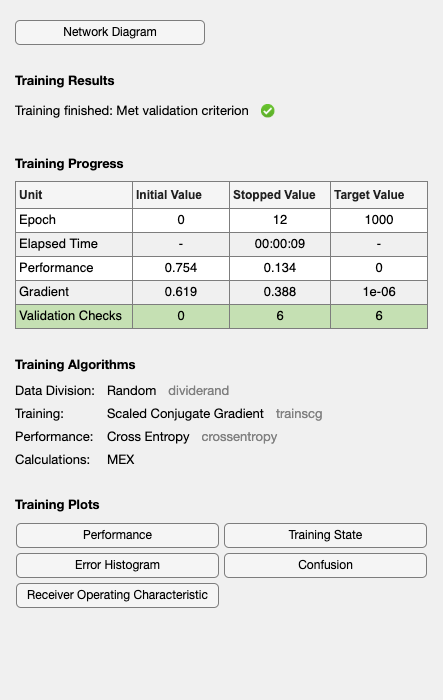

% Convert data to the format required by the neural network toolbox
X = X'; % Transpose so that columns are observations
y = y'; % Transpose for the same reason
% Create a Pattern Recognition Network
hiddenLayerSize = 10; % You can change this
net = patternnet(hiddenLayerSize);
% View the Network (kinda fun ngl)
% view(net);

% Set up Division of Data for Training, Validation, Testing
net.divideParam.trainRatio = 70/100;
net.divideParam.valRatio = 15/100;
net.divideParam.testRatio = 15/100;

% Choose a Performance Function
net.performFcn = 'crossentropy'; % for classification

% Choose a Training Function
net.trainFcn = 'trainscg'; % Scaled conjugate gradient
[net, tr] = train(net, X, y);

% Plot performance
% plotperform(tr);
testX = X(:, tr.testInd);
testY = y(:, tr.testInd);
testPredictions = net(testX)>0.5;
NNAccuracy = mean(testPredictions==testY);
%disp(['NN Accuracy: ', num2str(NNAccuracy)]);
% Convert predictions and true labels to logical for computation
testPredictions = logical(testPredictions);
testY = logical(testY);

% Calculate TP, FP, FN for the F1 score
TP = sum(testPredictions & testY);
FP = sum(testPredictions & ~testY);
FN = sum(~testPredictions & testY);

% Calculate precision and recall
precision = TP / (TP + FP);
recall = TP / (TP + FN);

% Handle cases where the denominator is zero to avoid division by zero
if (precision + recall) == 0
    NNf1Score = 0;
else
    % Calculate F1 score
    NNf1Score = 2 * (precision * recall) / (precision + recall);
end

% Display F1 score
%disp(['Neural Network F1 Score: ', num2str(NNf1Score)]);

## Accuracy Summary

Model_names = {'Logistic Regression', 'Decision Tree','GDA', 'SVM','NeuralNetwork'}

Model_names = 1×5 cell array
    {'Logistic Regression'}    {'Decision Tree'}    {'GDA'}    {'SVM'}    {'NeuralNetwork'}


Model_accuracy = [LRmeanAccuracy, DecisionTreeaccuracy, GDAaccuracy,SVMaccuracy, NNAccuracy]

Model_accuracy =     0.6600    0.7600    0.6000    0.6000    0.6667


Model_F1_score = [LRmeanF1Score, DTmeanF1Score, GDAf1Score, SVMf1Score, NNf1Score]

Model_F1_score =     0.7465    0.8494    0.7500    0.7143    0.8000


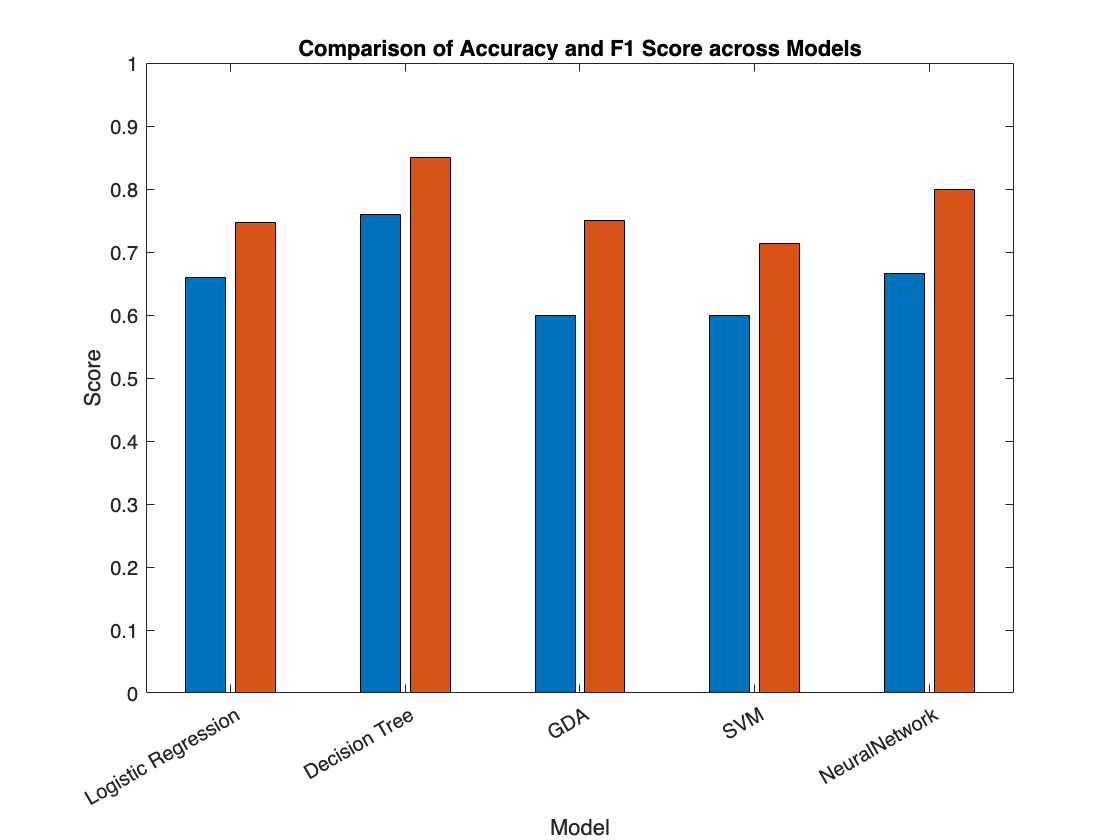

% Create the bar plot
figure;
bar([Model_accuracy; Model_F1_score]');

set(gca, 'xticklabel', Model_names);
xlabel('Model');
ylabel('Score');
ylim([0 1]);
title('Comparison of Accuracy and F1 Score across Models');

## PCA

This an unsupervised learning method. We are trying to see the low-dimensional representation of neural data given the condition of lever push/no-push and overall. 

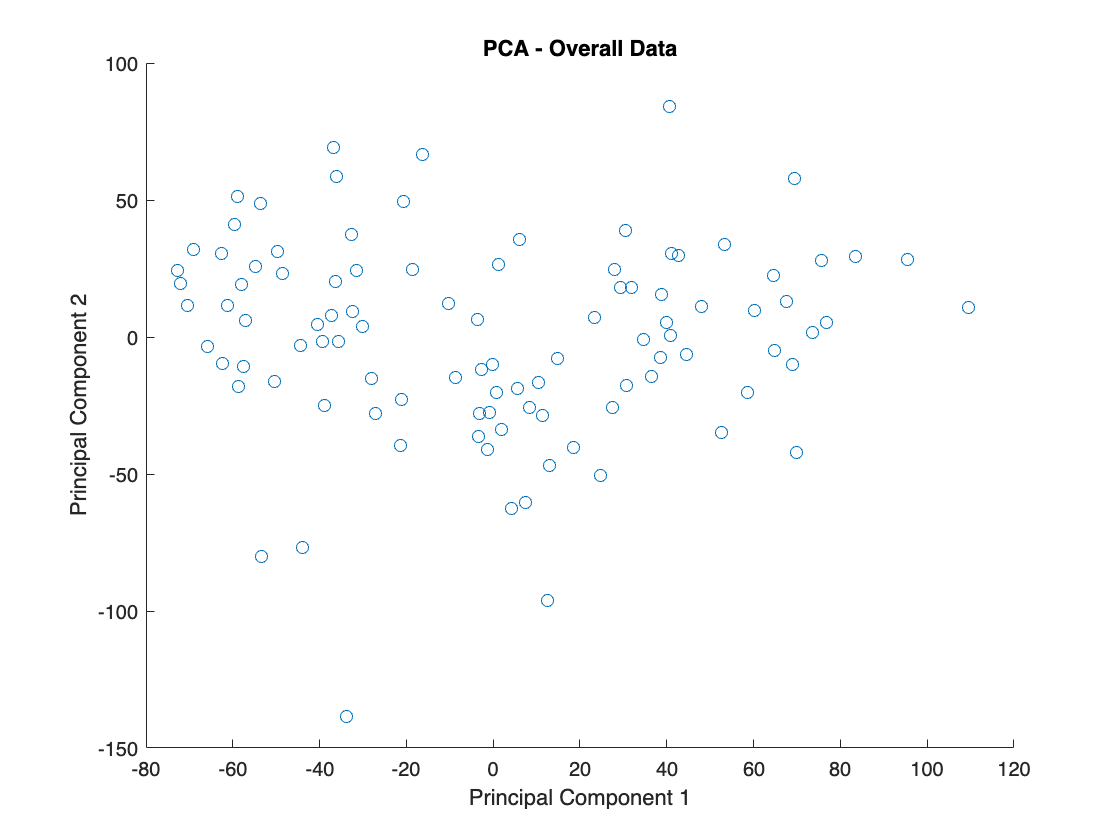

% PCA on the Overall Dataset
X=X';
y=y';
[coeff, score, ~, ~, explained] = pca(X);
figure; % Create a new figure
scatter(score(:,1), score(:,2));
xlabel('Principal Component 1');
ylabel('Principal Component 2');
title('PCA - Overall Data');

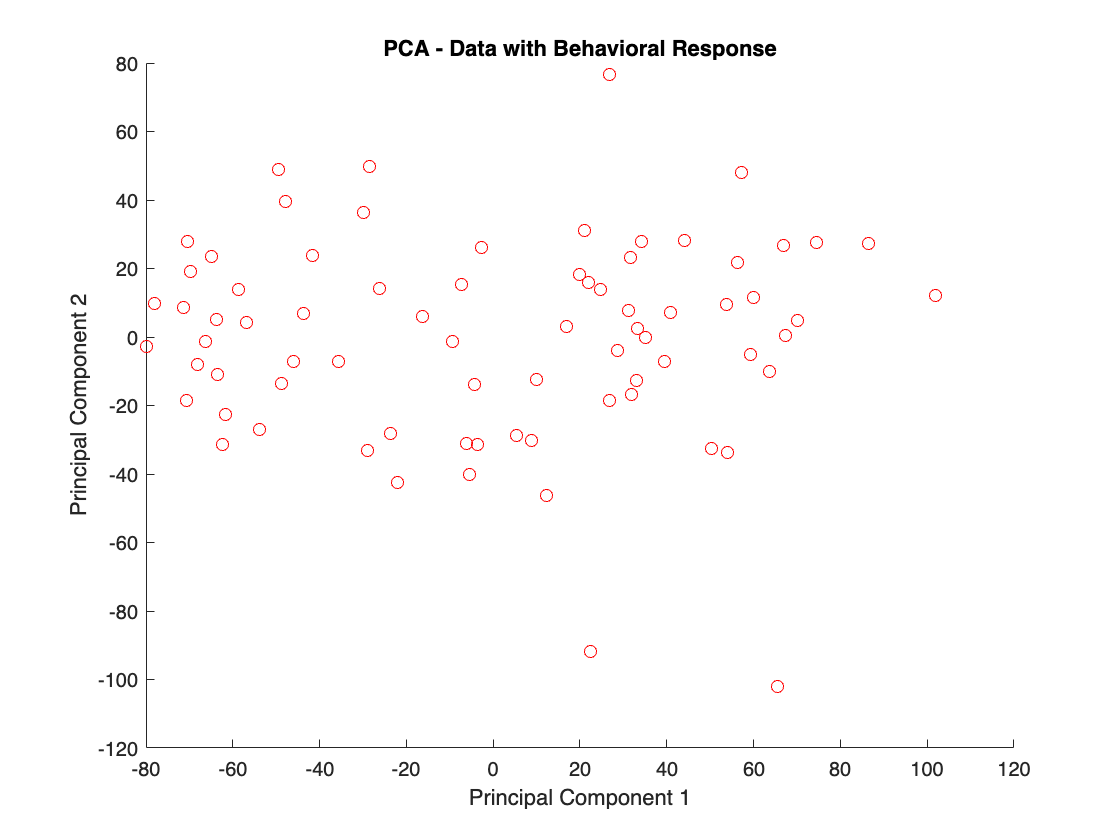

% PCA for Data with Behavioral Response
X_response = X(y == 1, :); % Data with behavioral response
[coeff_resp, score_resp, ~, ~, explained_resp] = pca(X_response);
figure; % Create a new figure
scatter(score_resp(:,1), score_resp(:,2), 'r');
xlabel('Principal Component 1');
ylabel('Principal Component 2');
title('PCA - Data with Behavioral Response');

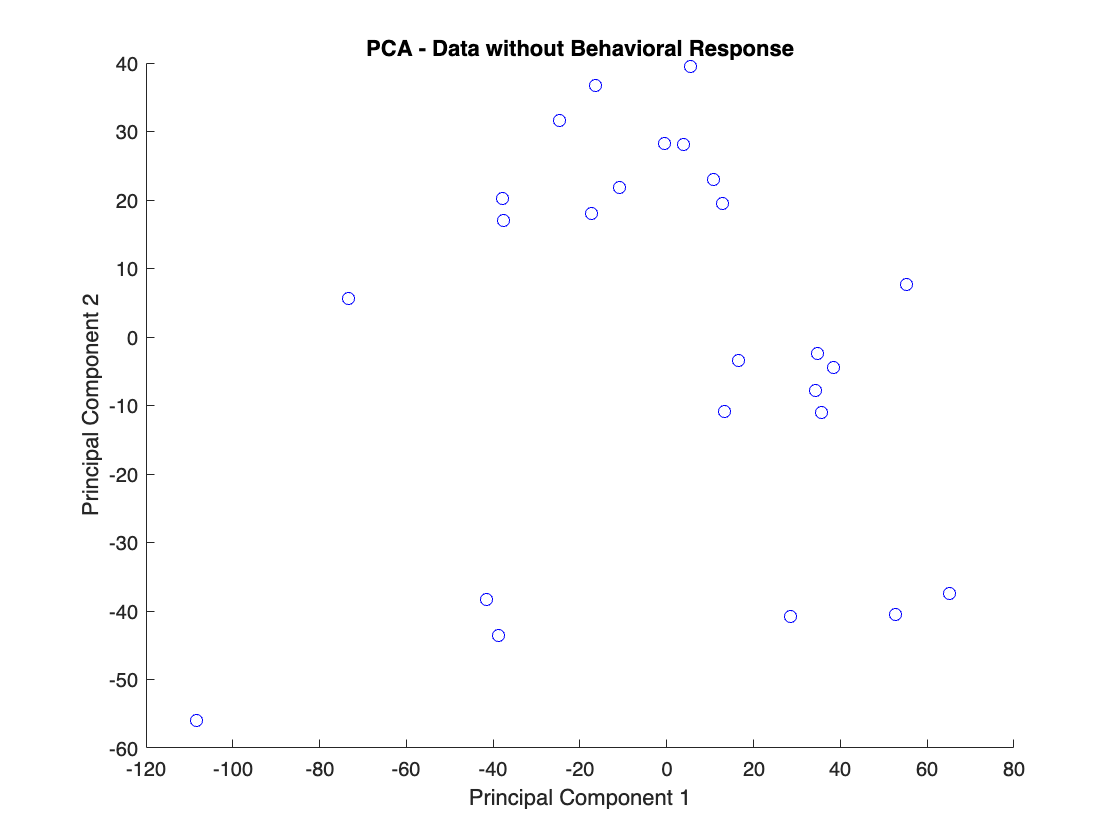

% PCA for Data without Behavioral Response
X_no_response = X(y == 0, :); % Data without behavioral response
[coeff_no_resp, score_no_resp, ~, ~, explained_no_resp] = pca(X_no_response);
figure; % Create a new figure
scatter(score_no_resp(:,1), score_no_resp(:,2), 'b');
xlabel('Principal Component 1');
ylabel('Principal Component 2');
title('PCA - Data without Behavioral Response');

cd("..")
cd("..")
cd("..")
data_summary_09_14 = struct('Model_Names', Model_names, 'F1', Model_F1_score, "Accuracy",Model_accuracy)

data_summary_09_14 = 1×5 struct array with fields:
    Model_Names
    F1
    Accuracy


save('data_summary_09_14.mat', 'data_summary_09_14');

## EM

% Choose the number of components for GMM
%numComponents = 2; 

% Fit the Gaussian mixture model
%gmm = fitgmdist(X, numComponents);

% The gmm object contains the fitted GMM
% You can obtain cluster assignments for each observation using cluster function
%clusterX = cluster(gmm, X);

% If you need to estimate the probabilities of each point belonging to each cluster
% P = posterior(gmm, X);

## K-means

% Assuming 'X' is your feature matrix

% Choose the number of clusters
%numClusters = 2; % for example

% Perform k-means clustering
%[idx, C] = kmeans(X, numClusters);